a) Create row vectors `d0` through `d9` to represent all 10 digits for the interval 0<=n<=999. Listen to each signal using `sound`. For example, `sound(d2, 8192)` should sound like the tone you hear when you push a '2' on the telephone.

% list row and column frequencies
omega_r = [0.5346 0.5906 0.6535 0.7217];
omega_c = [0.9273 1.0247 1.1328];

% create signals for each digit
n = 0:999;
d0 = sin(omega_r(4)*n) + sin(omega_c(2)*n);
d1 = sin(omega_r(1)*n) + sin(omega_c(1)*n);
d2 = sin(omega_r(1)*n) + sin(omega_c(2)*n);
d3 = sin(omega_r(1)*n) + sin(omega_c(3)*n);
d4 = sin(omega_r(2)*n) + sin(omega_c(1)*n);
d5 = sin(omega_r(2)*n) + sin(omega_c(2)*n);
d6 = sin(omega_r(2)*n) + sin(omega_c(3)*n);
d7 = sin(omega_r(3)*n) + sin(omega_c(1)*n);
d8 = sin(omega_r(3)*n) + sin(omega_c(2)*n);
d9 = sin(omega_r(3)*n) + sin(omega_c(3)*n);

% uncomment to listen to each signal
%sound(d0,8192)
%sound(d1,8192)
%sound(d2,8192)
%sound(d3,8192)
%sound(d4,8192)
%sound(d5,8192)
%sound(d6,8192)
%sound(d7,8192)
%sound(d8,8192)
%sound(d9,8192)

b) Use the function `fft` to compute samples of $D_2(e^{j \omega})$ and $D_9(e^{j \omega})$ at $\omega_k = 2\pi k /2048$. Plot the magnitudes of the DTFTs for these signals, and confirm that the peaks fall at the specified frequencies.

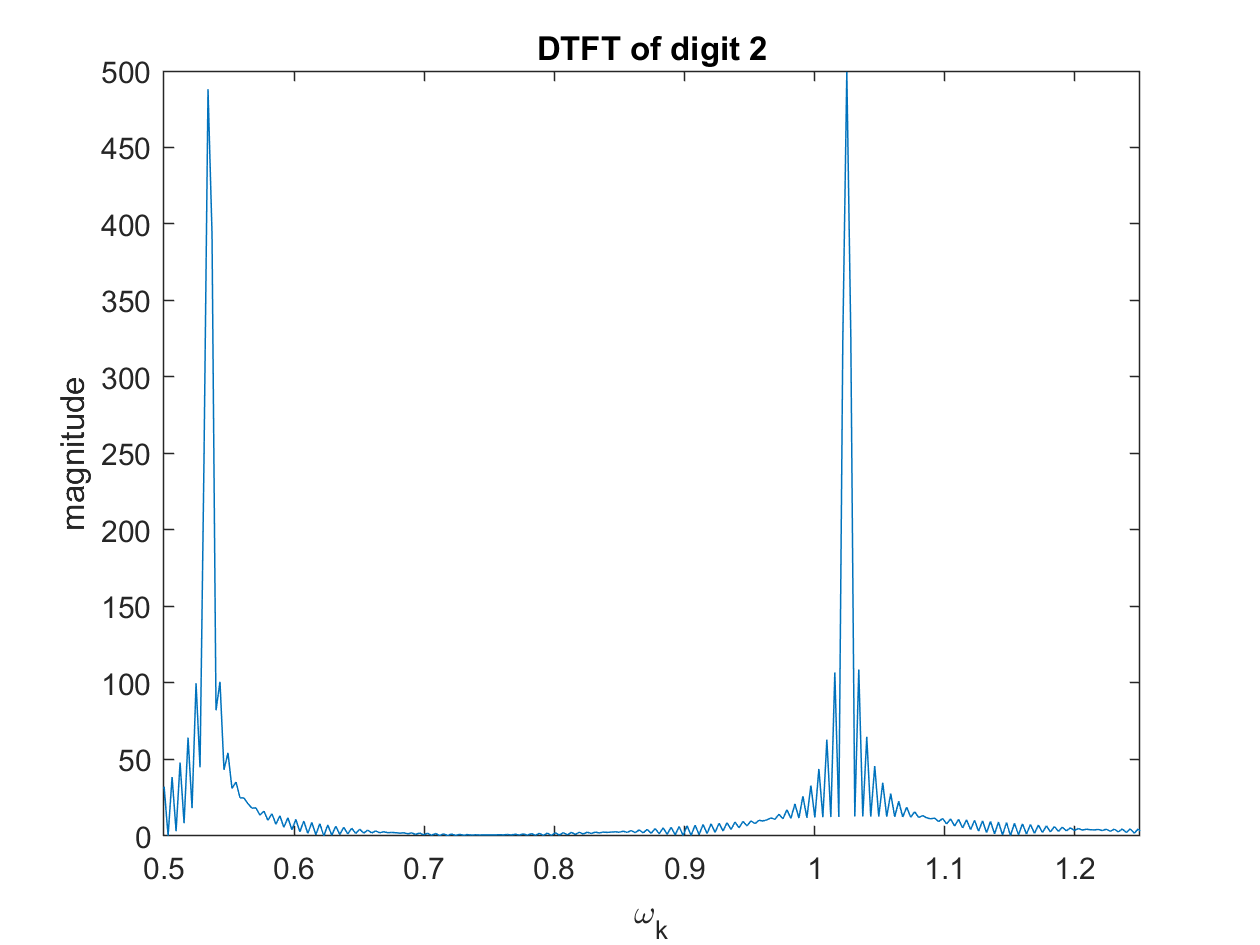

% make sure omega is same length as fft
k = 0:2047;
omega = k*((2*pi)/2048);

% find the fft for each digit
X1 = fft(d1,2048);
X2 = fft(d2,2048);
X3 = fft(d3, 2048);
X4 = fft(d4, 2048);
X5 = fft(d5, 2048);
X6 = fft(d6, 2048);
X7 = fft(d7, 2048);
X8 = fft(d8, 2048);
X9 = fft(d9, 2048);

% plot the magnitude of the fft for digit 2 
figure
plot(omega, abs(X2));
title('DTFT of digit 2');
xlim([0.5 1.25]);
xlabel('\omega_k');
ylabel('magnitude');

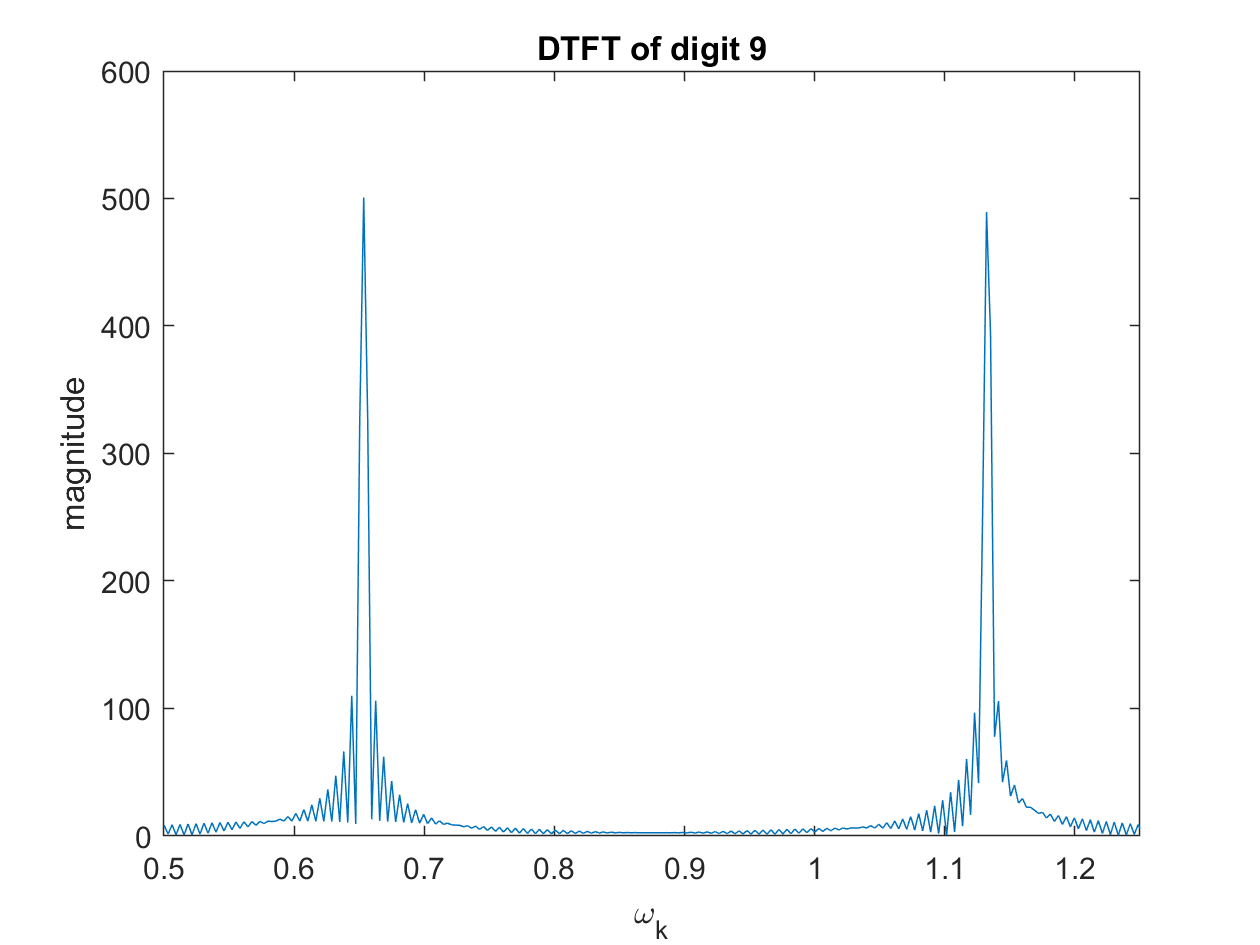


% plot the magnitude of the fft for digit 2 
figure
plot(omega, abs(X9));
title('DTFT of digit 9');
xlim([0.5 1.25]);
xlabel('\omega_k');
ylabel('magnitude');

c) Define `space` to be a row vector with 100 samples of silence using `zeros`. Define `phone` to be your phone number by appending the appropriate signals and `space. Play your phone number using sound and plot the spectra for each digit.`

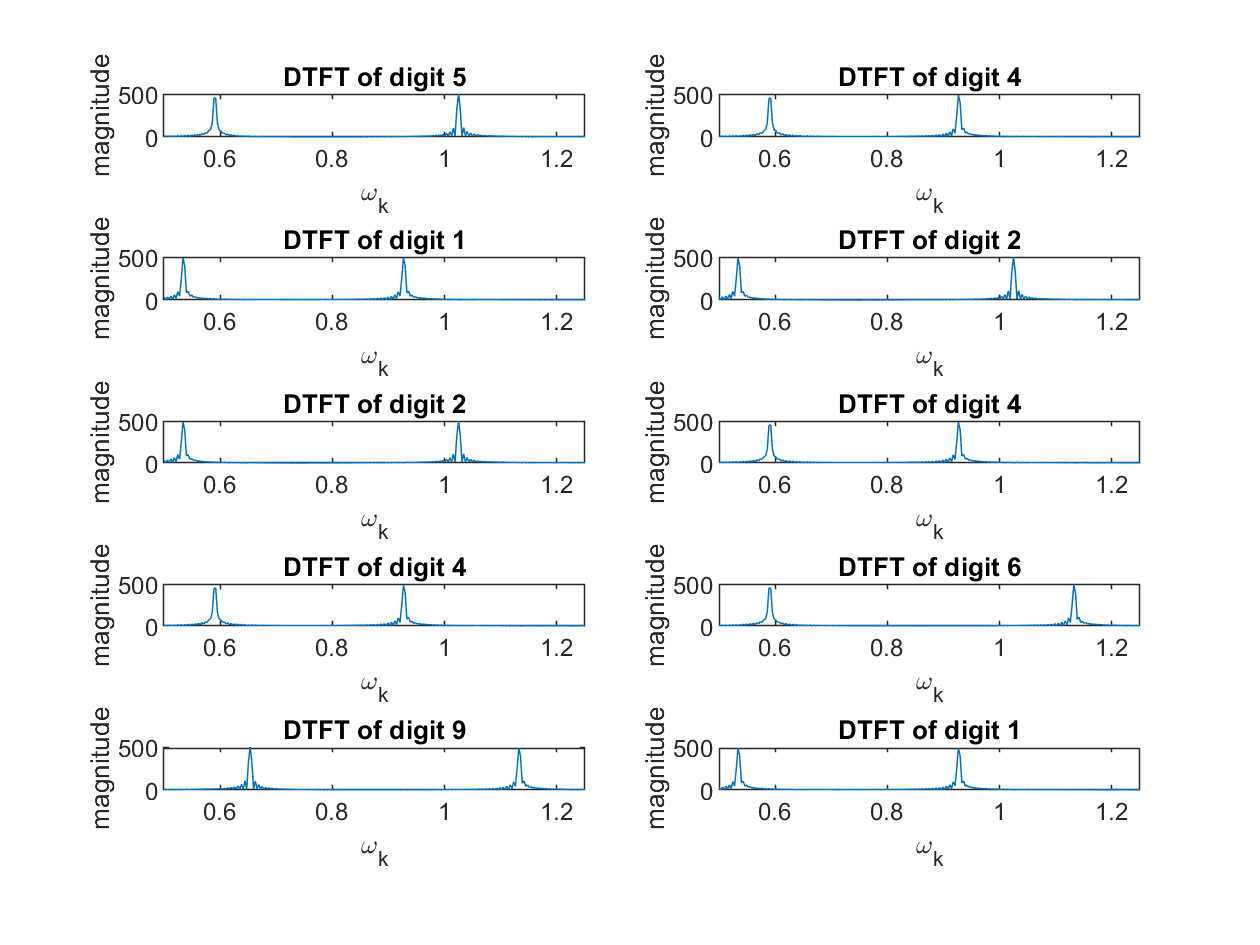

% define a variable to hold signals for each digit of my phone number,
% separated by spaces for ease of listening
empty = zeros(100);
space = empty(1,:);
phone = [d5 space d4 space d1 space d2 space d2 space d4 space d4 space d6 space d9 space d1];

% play the dialtones for my phone number
sound(phone, 8192);

figure  % plot the magnitudes of each digit's signal's DTFT

subplot(5,2,1);
plot(omega, abs(X5));
title('DTFT of digit 5');
xlim([0.5 1.25]);
xlabel('\omega_k');
ylabel('magnitude');

subplot(5,2,2);
plot(omega, abs(X4));
title('DTFT of digit 4');
xlim([0.5 1.25]);
xlabel('\omega_k');
ylabel('magnitude');

subplot(5,2,3);
plot(omega, abs(X1));
title('DTFT of digit 1');
xlim([0.5 1.25]);
xlabel('\omega_k');
ylabel('magnitude');

subplot(5,2,4);
plot(omega, abs(X2));
title('DTFT of digit 2');
xlim([0.5 1.25]);
xlabel('\omega_k');
ylabel('magnitude');

subplot(5,2,5);
plot(omega, abs(X2));
title('DTFT of digit 2');
xlim([0.5 1.25]);
xlabel('\omega_k');
ylabel('magnitude');

subplot(5,2,6);
plot(omega, abs(X4));
title('DTFT of digit 4');
xlim([0.5 1.25]);
xlabel('\omega_k');
ylabel('magnitude');

subplot(5,2,7);
plot(omega, abs(X4));
title('DTFT of digit 4');
xlim([0.5 1.25])
xlabel('\omega_k');
ylabel('magnitude');

subplot(5,2,8);
plot(omega, abs(X6));
title('DTFT of digit 6');
xlim([0.5 1.25]);
xlabel('\omega_k');
ylabel('magnitude');

subplot(5,2,9);
plot(omega, abs(X9));
title('DTFT of digit 9');
xlim([0.5 1.25]);
xlabel('\omega_k');
ylabel('magnitude');

subplot(5,2,10);
plot(omega, abs(X1));
title('DTFT of digit 1');
xlim([0.5 1.25]);
xlabel('\omega_k');
ylabel('magnitude');

d) Using `fft`, compute 2048 evenly spaced samples of the DTFT for each digit of `x1`. 

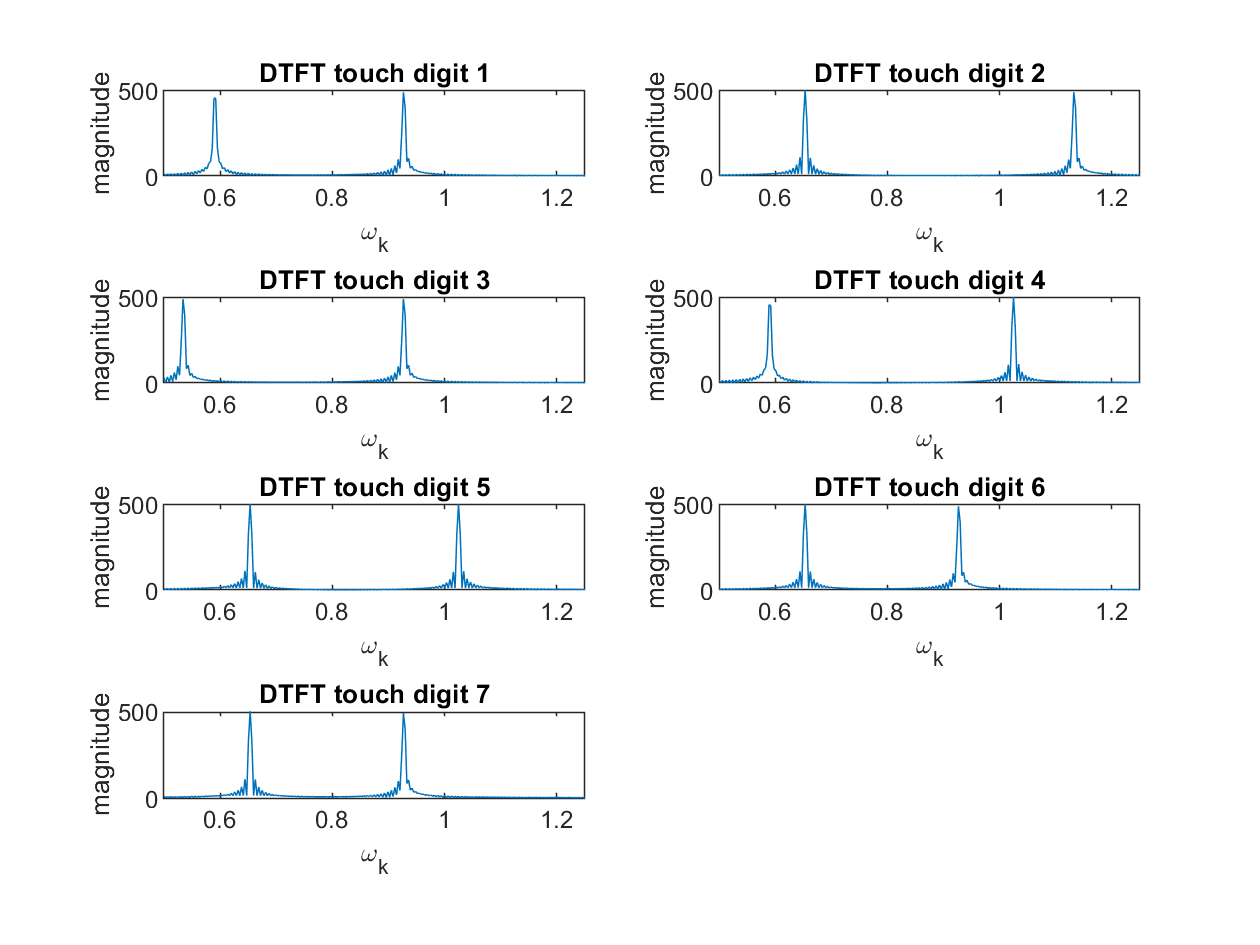

% load file containing variable x1
load touch.mat;

% parse out each digit of x1
d1_t = x1(1:1000);
d2_t = x1(1101:2100);
d3_t = x1(2201:3200);
d4_t = x1(3301:4300);
d5_t = x1(4401:5400);
d6_t = x1(5501:6500);
d7_t = x1(6601:7600);

% find the fft of each digit of x1
X1_t = fft(d1_t,2048);
X2_t = fft(d2_t,2048);
X3_t = fft(d3_t, 2048);
X4_t = fft(d4_t, 2048);
X5_t = fft(d5_t, 2048);
X6_t = fft(d6_t, 2048);
X7_t = fft(d7_t, 2048);

% plot the magnitude of the DTFT of each digit of x1
figure
subplot(4,2,1);
plot(omega, abs(X1_t));
title('DTFT touch digit 1');
xlim([0.5 1.25]);
xlabel('\omega_k');
ylabel('magnitude');

subplot(4,2,2);
plot(omega, abs(X2_t));
title('DTFT touch digit 2');
xlim([0.5 1.25]);
xlabel('\omega_k');
ylabel('magnitude');

subplot(4,2,3);
plot(omega, abs(X3_t));
title('DTFT touch digit 3');
xlim([0.5 1.25]);
xlabel('\omega_k');
ylabel('magnitude');

subplot(4,2,4);
plot(omega, abs(X4_t));
title('DTFT touch digit 4');
xlim([0.5 1.25]);
xlabel('\omega_k');
ylabel('magnitude');

subplot(4,2,5);
plot(omega, abs(X5_t));
title('DTFT touch digit 5');
xlim([0.5 1.25]);
xlabel('\omega_k');
ylabel('magnitude');

subplot(4,2,6);
plot(omega, abs(X6_t));
title('DTFT touch digit 6');
xlim([0.5 1.25]);
xlabel('\omega_k');
ylabel('magnitude');

subplot(4,2,7);
plot(omega, abs(X7_t));
title('DTFT touch digit 7');
xlim([0.5 1.25]);
xlabel('\omega_k');
ylabel('magnitude');

By visual inspection, the seven digits are 4915877.

e) Use your knowledge of the sampling rate to determine the actual continuous time frequencies for each digit on the phone keypad. List all frequencies in a matrix corresponding to the keypad, and describe how you calculated them.

% define conversion factor from sampled frequency to frequency in Hz
conversion = 8192 / (2*pi);

% calculate and display keypad frequencies in Hz
freq_r = conversion * omega_r;
freq_c = conversion * omega_c;
freq_r

freq_r =   697.0100  770.0227  852.0315  940.9505


freq_c

freq_c = 	1.0e+03 *

    1.2090    1.3360    1.4769
